# Visualization of graph data

## Small graph data

addpath("functions")
set(0,'DefaultFigureWindowStyle','docked')

% this was last executed on 4rd January 12:03
% pathNodes = "data\small_graph_nodes.txt";
% pathEdges = "data\small_graph_edges.txt";
% [nodes,edges,n] = merg(pathNodes,pathEdges);
% [emb,M,P,Cos,Sin] = build(pathNodes,pathEdges);
load materials\small_graph_data_merged.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

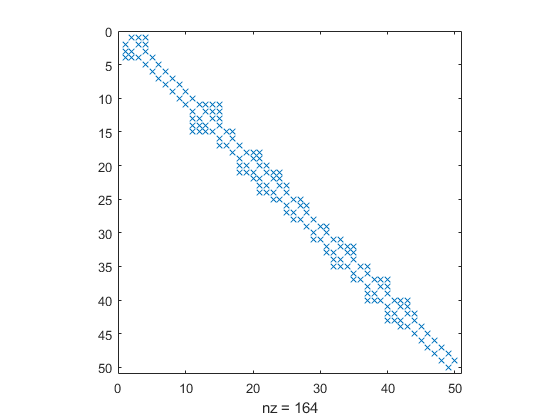

spy(Cos,'x');

% spy(Sin,'xr');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

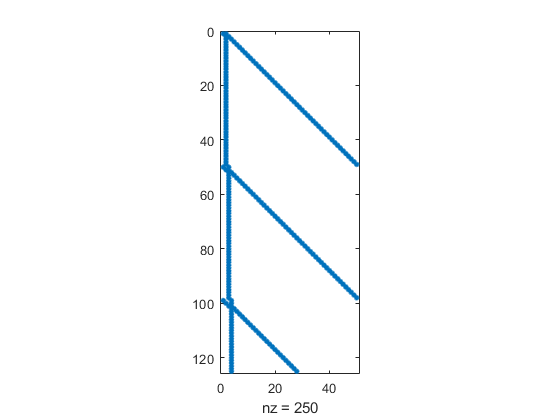

spy(headN(M,ceil(2.5*n)));

Before we go on plotting, we created a function *(see addpoints)* to plot some points over a color gradient to keep track of the location of some specific points. Through this we get a better grasp of the embeddings' changes. *(See *[https://de.mathworks.com/help/matlab/ref/uisetcolor.html](https://de.mathworks.com/help/matlab/ref/uisetcolor.html)*)*

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

Plot now the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

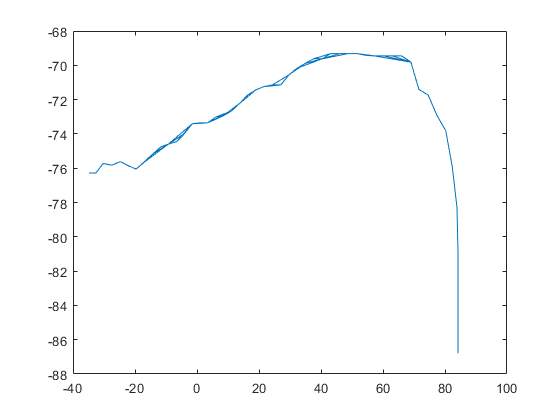

gplot(Cos,nodes(:,2:3))

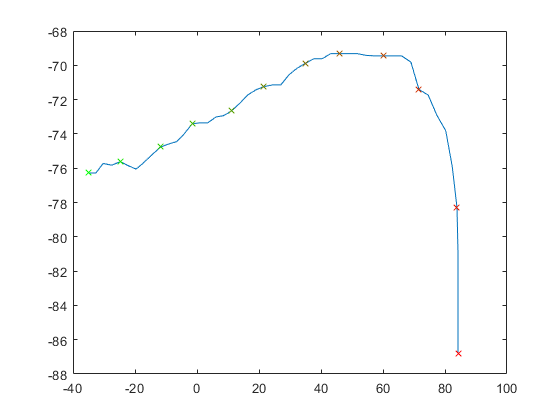

% the following two lines were rendered unnecessary due to
% plotcolorgradient()
% plot(nodes(:,2),nodes(:,3),".")
% addpoints(n/4,col1,col2,nodes(:,2:3))
plotcolorgradient(n/4,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% plotcolorgradient(n/4,col1,col2,emb1,true,true)

Display the embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

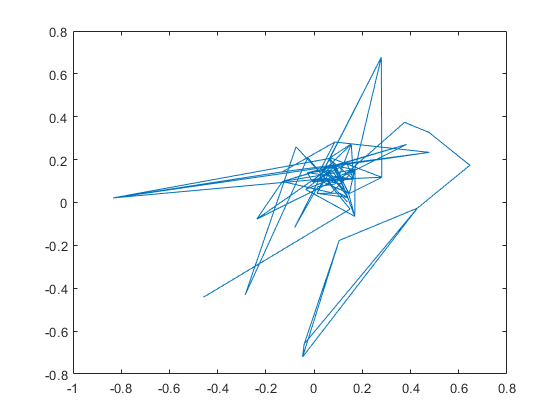

gplot(Cos,emb)

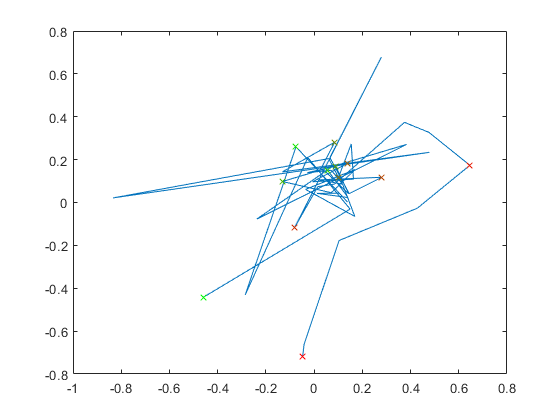

% plot(emb(:,1),emb2(:,2),".")
plotcolorgradient(n/4,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let us try **clustering **with **dbscan() **and **kmeans()**.

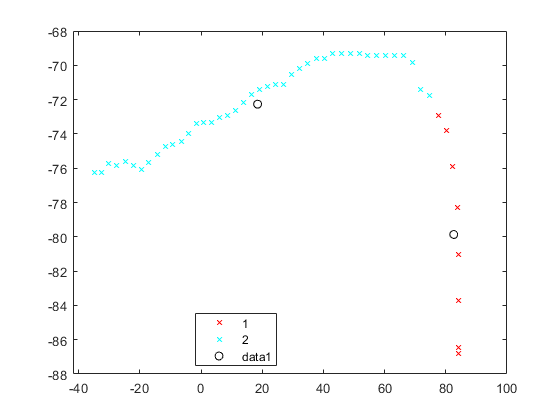

plotCluster(nodes,6,5,'on',false,"db");

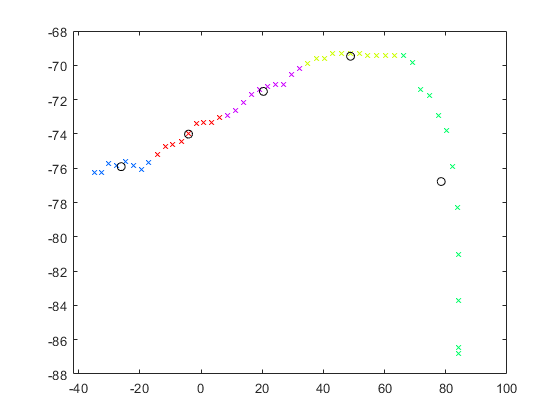

plotCluster(nodes,1.2,5,'off',false,"km");

### Aftermath

clc
clearvars -except nodes edges n emb M P Cos Sin

% this was last executed on 4rd January 12:03
% save materials\small_graph_data_merged.mat

## Large graph data

Here we want to use the **large data set** Tristan gave us instead of the partial one above. Due to the large number of nodes and edges we cannot calculate an adjacency matrix. This would break the limit of data storage as it demands **9.4GB**. As for now we just display the nodes without interconnecting edges.

% this was last executed on 4rd January 12:03
% pathNodes = "data\large_graph_nodes.txt";
% pathEdges = "data\large_graph_edges.txt";
% [nodes,edges,n] = merg(pathNodes,pathEdges);
% [emb,M,P,Cos,Sin] = build(pathNodes,pathEdges);
load materials\large_graph_data_merged.mat

### Visualization

The sparsity patterns for the Sin and Cos matrices.

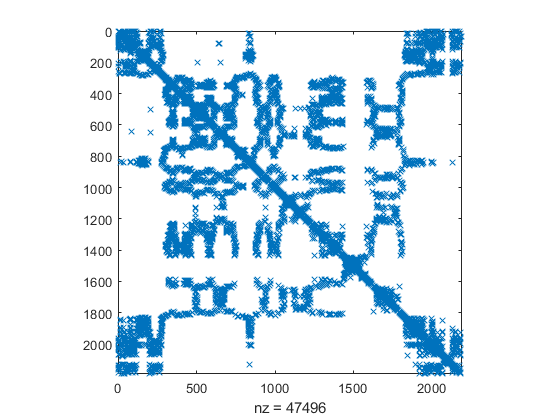

spy(Cos,'x');

% spy(Sin,'xr');

The head of the M matrix. Its pattern should be falling diagonals with verticals at each iteration.

% spy(headN(M,ceil(2.5*n)));

Plot here the actual graph that is given. **Cos** does function as the adjacency matrix here. For the real adjacency matrix get the nonzeros from Cos. If no adjacency is given we can take only the vertices without interconnections. *(See section ****large graph****)*

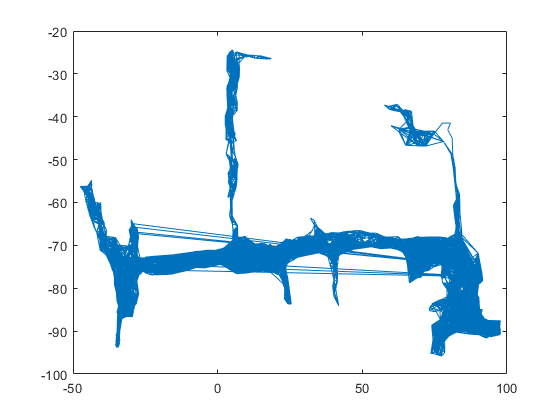

% uisetcolor for the colors
col1 = [1, 0, 0];
col2 = [0, 1, 0];

gplot(Cos,nodes(:,2:3))

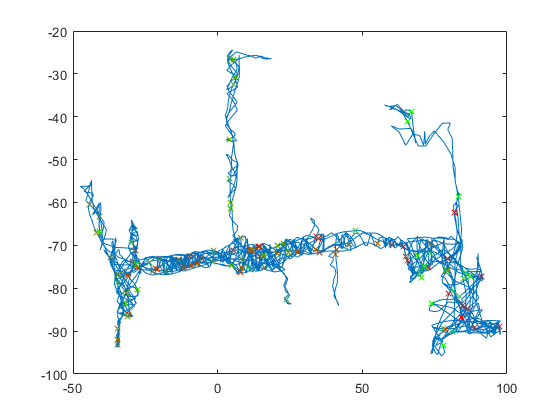

% plot(nodes(:,2),nodes(:,3),".")
plotcolorgradient(n/20,col1,col2,nodes(:,2:3),true,true)

Display the first embedding solution. This embedding was calculated by improper usage of **inv()**.

Update 21-01-04: emb1 no longer available

% gplot(Cos,emb1)
% % plot(emb1(:,1),emb1(:,2),".")
% plotcolorgradient(2,col1,col2,emb1,true,true)

Display the second embedding solution. This embedding was calculated by the proper way of **A\b**. Here **b** was a matrix as well. *(See ****building.mlx****)*

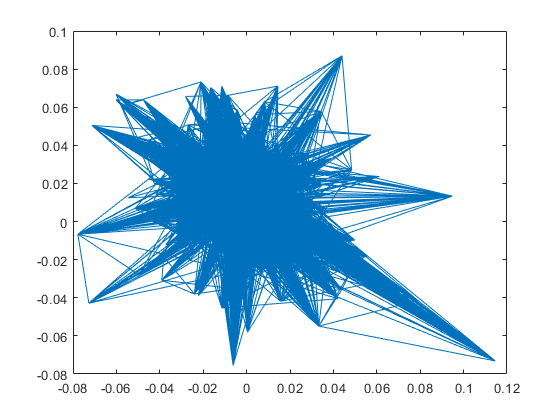

gplot(Cos,emb)

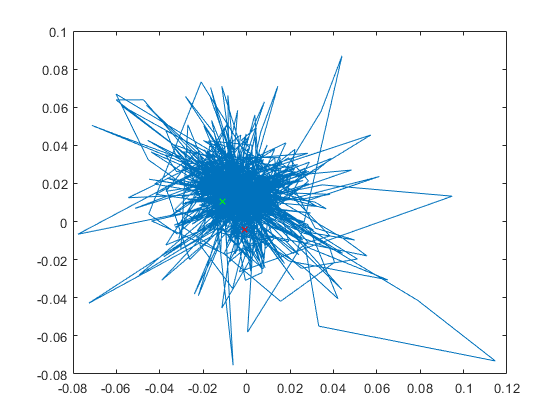

% plot(emb2(:,1),emb(:,2),".")
plotcolorgradient(2,col1,col2,emb,true,true)

On this last graph there is visible some circular structure. This is interesting in a way that it differs the first version of the improper usage of **inv()** a lot. This might be interesting for understanding the desired solution of embeddings and worth discussing more.

### Clustering

Let's again cluster, this time the large graph. It is a bit more interesting than the small graph.

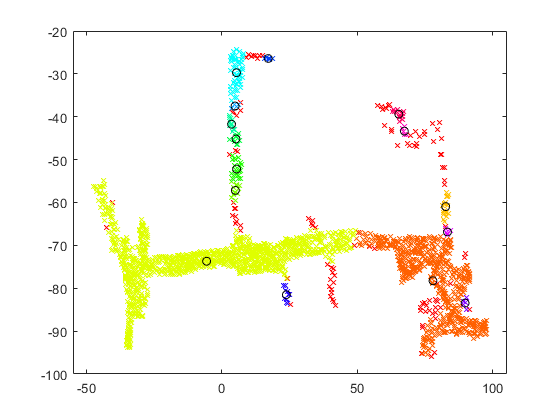

plotCluster(nodes,1.5,5,'off',false,"db");

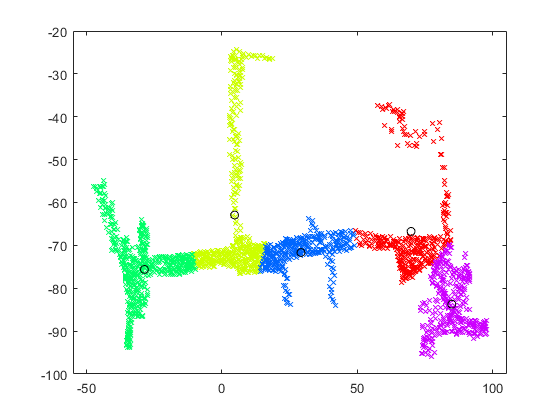

plotCluster(nodes,1.2,5,'off',false,"km");

### Aftermath

clc
clearvars -except nodes edges n emb M P Cos Sin

% this was last executed on 4rd January 12:03
% save materials\large_graph_data_merged.mat

## Tests

### 01

addpath("functions")

pathNodes = "data\01_nodes.txt";
pathEdges = "data\01_edges.txt";
[nodes,edges,n] = merg(pathNodes,pathEdges);
[emb,M,P,Cos,Sin] = build(pathNodes,pathEdges);


building M...
Elapsed time is 0.000698 seconds.

building P...
Elapsed time is 0.000382 seconds.



col1 = [0, 1, 0];
col2 = [1, 0, 0];

% spy(Cos,'x');
% spy(M)

https://de.mathworks.com/help/matlab/ref/tiledlayout.html

tl = tiledlayout(1,2)

tl =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 2]
            Padding: 'normal'
        TileSpacing: 'normal'

  Show all properties


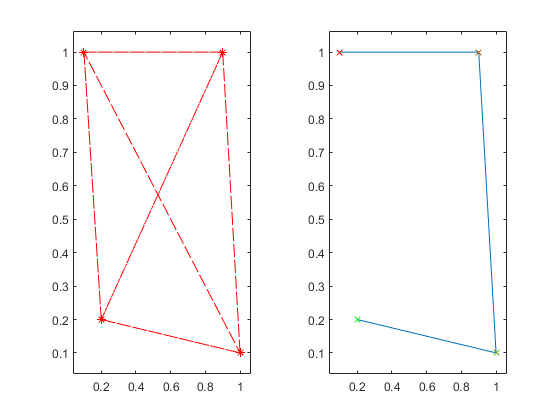

% tl.GridSize
nexttile
gplot(Cos,nodes(:,2:3),'-.*r')
axis padded
nexttile
plotcolorgradient(n,col1,col2,nodes(:,2:3),true,true)
axis padded

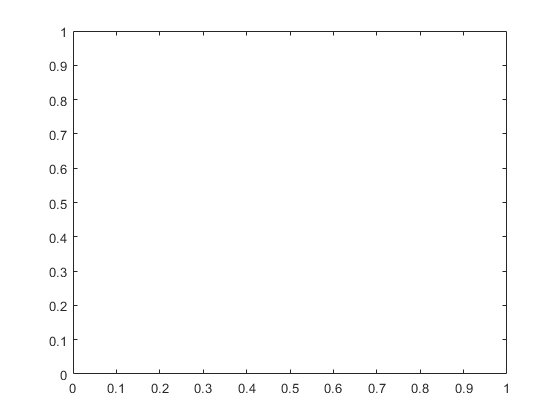

figure % or tiledlayout(1,1)
gplot(Cos,emb)

why is the embedding not calculated as desired?

% plot(emb2(:,1),emb(:,2),".")
% plotcolorgradient(2,col1,col2,emb,true,true)

https://de.mathworks.com/matlabcentral/answers/692515-how-do-you-end-a-tiledlayout-object

% tiledlayout(1,2);
% [X,Y,Z] = peaks(20);
% % Tile 1
% nexttile
% surf(X,Y,Z)
% % Tile 2
% nexttile
% contour(X,Y,Z)
% % New plot
% figure
% x=1:5;
% y=x.^2;
% plot(x,y)

### Aftermath

clc
clearvars -except nodes edges n emb M P Cos Sin

% save materials?

TODO:

Consider making the directed graph an undirected on from Tristans data. For this we need to check first whether the two edge angles are opposite to each other...

If they are **not, **then we cannot do this! 

If they **are,** then we can savely generate an undirected graph from the data

EDIT

The in and out angles should not be the same, as we precisely for this occasion to want to minimize the angular error. The shift of angles over the graph (north direction) should affect the two respective directed edges between two nodes in such way, that the angles do not match...

Check again on this statement!

For visualization: We add up the north shifts of each node to the angles of the outgoing edges of the respective nodes, so we get it drawing accordingly in the graphs! With sufficient north shifts we should be able to see, that the edges do not hit target (the ingoing nodes), as they do in a graph without north shifts...

For this we need to draw not a gplot() graph, as the lines are not drawn according to the angles there:

### drawing function


building M...
Elapsed time is 0.000046 seconds.

building P...
Elapsed time is 0.000033 seconds.


draw("01");

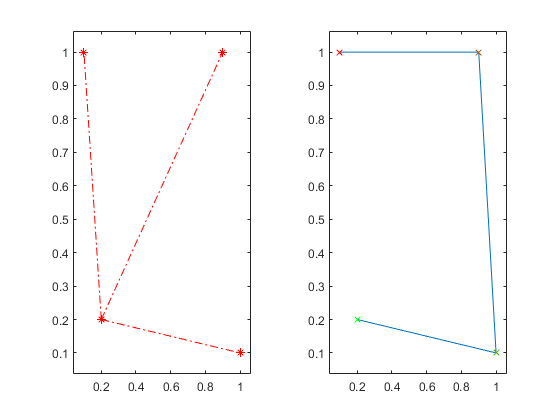


building M...
Elapsed time is 0.000036 seconds.

building P...
Elapsed time is 0.000023 seconds.


draw("02");


building M...
Elapsed time is 0.000047 seconds.

building P...
Elapsed time is 0.000030 seconds.


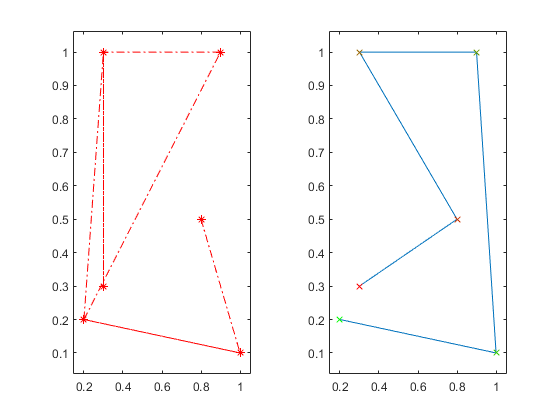

draw("03")

function draw(number)
    addpath("functions")
    
    pathNodes = "data\"+number+"\nodes.txt";
    pathEdges = "data\"+number+"\edges.txt";
    [nodes,edges,n] = merg(pathNodes,pathEdges);
    [emb,M,P,Cos,Sin] = build(pathNodes,pathEdges);
    
    col1 = [0, 1, 0];
    col2 = [1, 0, 0];
    
    % spy(Cos,'x');
    % spy(M)
    graphs = tiledlayout(1,2);
    % tl.GridSize
    nexttile
    gplot(Cos,nodes(:,2:3),'-.*r')
    axis padded
    nexttile
    plotcolorgradient(n,col1,col2,nodes(:,2:3),true,true)
    axis padded
    figure
end